# **Animation using MATLAB**

Day 4, Session-1 of Five day Workshop on Matlab Applications on "Animation using MATLAB & Graphical User Interface"  at Department of Mechanical Engineering, **Madanapalle Institute of Technology & Science**, Madanapalle, Andhra Pradesh, India (11th November 2021,Thursday).

## Content:

- Why do we need animated content?

- Animation using matlab.

- 2D animated plots (Basic approach).

- 2D animated plots (using inbuilt functions).

- Saving the animation as a video file.

- 3D animated plots(Basic approach).

- 3D animated plots using (inbuilt functions).

### Why do we need animated content?

- showcases complex pictures, ideas, concepts, and a great deal of data in a short, simple, visually appealing video.

- More expressive (especially in the time-series data)

### How to perform animation using matlab?

Following are the steps to achieve this:

- Run the simulation or get the data

- Draw/Render the scenario at the time t(k)

- Take the snapshot of the scenario

- Advance time to t(k+1)

- Save the video

### First Program

**2D animated plots: slow motion plots (Basic approach).**

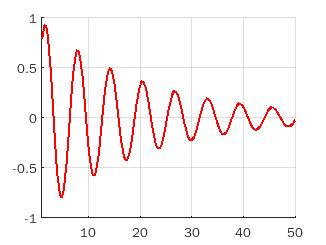

clear;  close all;  clc;
t = 0:0.05:50; % time in seconds with the gap of 0.05secs
y1 = exp(-0.05*t) .* sin(t);
% y1 = 0.7 .* cos(0.2/0.4 .* t);
limits_of_axis = [1 50 -1 1]; % [xmin xmax ymin ymax]
axis(limits_of_axis);
hold on
% Plot only the intial values
h1 = plot(t(1),y1(1),'Color',[1,0,0],'LineWidth',2); 
grid on
% Loop through the all the values
for k=2:length(t)
    set(h1,'xdata',t(1:k),'ydata',y1(1:k));
    pause(0.01); % pauses execution for n seconds before continuing
end
hold off

### Second Program

**2D animated plots: slow motion plots (Using **`comet`** functions).**

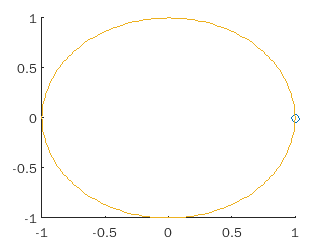

clear;  close all;  clc;
t = 0:pi/100:2*pi;
y = sin(t);
x = cos(t);
comet(x,y);

### Third Program

**2D animated plots: slow motion plots (Using **`comet`** functions).**

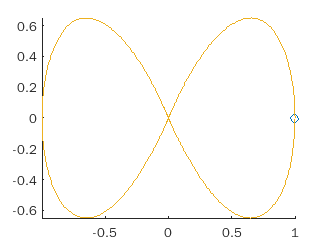

clear;  close all;  clc;
t = 0:.01:2*pi;
x = cos(t) .* (cos(t).^2);
y = sin(2.*t) .* (cos(t).^2);
comet(x,y);

### Fourth Program

**2D animated plots: slow motion plots (Using **`animatedline`** functions).**

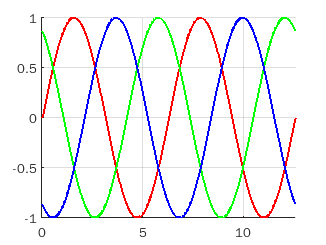

clear;  close all;  clc;
anim_line_r = animatedline('Color',[1,0,0],'LineWidth',2);
anim_line_g = animatedline('Color',[0,1,0],'LineWidth',2);
anim_line_b = animatedline('Color',[0,0,1],'LineWidth',2);

axis([0 4*pi -1 1]);
t = linspace(0,4*pi,1000);

yr = sin(t); yg = sin(t+(2*pi/3)); yb = sin(t+(4*pi/3));
grid on
for k=1:length(t)
    % Add points to animated lines
    addpoints(anim_line_r,t(k),yr(k));
    addpoints(anim_line_g,t(k),yg(k));
    addpoints(anim_line_b,t(k),yb(k));
    drawnow limitrate  % Update figures and process callbacks
    pause(0.01);
end

### Fifth Program

**Slow moving markers using values.**

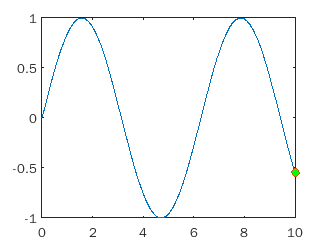

% trace a marker along a line by updating the data properties of the marker.
clear;  close all;  clc;
x = linspace(0,10,1000);
y = sin(x);
plot(x,y);
hold on
p = plot(x(1),y(1),'o','MarkerFaceColor','green');
hold off
% Loop through the all the values
for k=2:length(x)
    p.XData = x(k);
    p.YData = y(k);
    s = sprintf('   %0.4f, %0.4f',x(k),y(k));
    ht = text(x(k),y(k),s,'Color','[1 0 1]','FontSize',12);
    drawnow limitrate
    pause(0.01);
    delete(ht);
end

### Sixth Program

**Making video of Animated plots.**

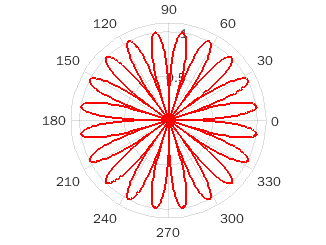

clear;  close all;  clc;
% Save animated plot as a video
v = VideoWriter('animated_plot.avi');
v.FrameRate = 1;
open(v)
theta = 0:pi/500:2*pi;
for k = 1:10
    r = sqrt(abs(sin(k*theta)));
    polarplot(theta,r,'r','LineWidth',2)
    rlim([0 1.1])
    % Capture axes or figure as movie frame
    frame = getframe(gcf);
    % write the current frame to the video file
    writeVideo(v,frame); 
    pause(1);
end

close(v)

### Seventh Program

**3D plots: plot data points on three axes in the attempt to show the relationship between three variables**

% clear;  close all;  clc;
% t = 0:pi/50:10*pi;
% st = sin(t);
% ct = cos(t);
% plot3(st,ct,t)

**3D Animated plots: Basic Approach.**

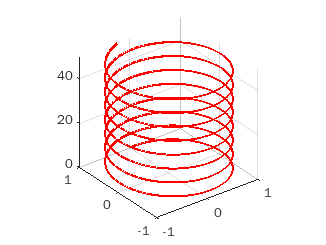

clear;  close all;  clc;
% Plot 3D curve in slow motion
t = 0:0.01:50;
x = sin(t);
y = cos(t);
z = t;
h = plot3(x(1),y(1),z(1),'r','LineWidth',2);
axis([-1 1 -1 1 0 50]);
axis square
grid on
hold on
for k=2:length(t)
    set(h,'xdata',x(1:k),'ydata',y(1:k),'zdata',z(1:k));
    pause(0.0002);
end
hold off

### Eighth Program

**3D Animated plots: Basic Approach (animating two plots simultaneously).**

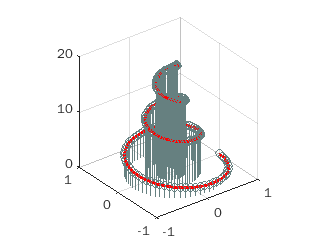

clear;  close all;  clc;
t = 0:0.1:20;
w = 0.1+1i; f=exp(-w*t);
% plot its real vs imaginery values w.r.t the progressing time
x = real(f); y=imag(f); z=t;

plot_1 = stem3(x(1),y(1),z(1),'Color',[0.4,0.5,0.5]);
axis([-1 1 -1 1 0 20]);
axis square
grid on
hold on
plot_2 = plot3(x(1),y(1),z(1),'Color',[1,0,0],'LineWidth',2);

for k=2:length(t)
    set(plot_1,'xdata',x(1:k),'ydata',y(1:k),'zdata',z(1:k));
    set(plot_2,'xdata',x(1:k),'ydata',y(1:k),'zdata',z(1:k));
    pause(0.1);
end
hold off

### Nineth Program

**3D Animated plots: using inbuilt function (**`comet3`**).**

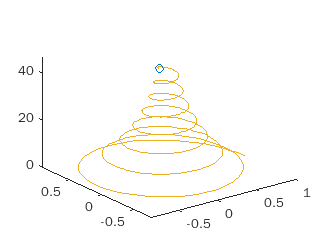

clear;  close all;  clc;
t = 0:0.1:pi*15;
x = exp(-0.05*t) .* cos(t);
y = exp(-0.05*t) .* sin(t);
z = t;
comet3(x,y,z);

### Tenth Program

**3D Animated surface plot.**

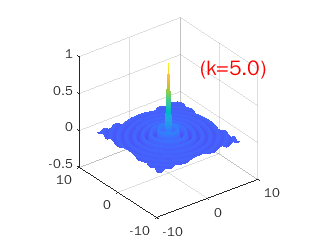

clear;  close all;  clc;
[x,y] = meshgrid(-8:0.2:8);
r = sqrt(x.^2 + y.^2)+eps;

for k=0.1:0.01:5
    z = sin(k*r) ./ (k*r);
    mesh(x,y,z, 'FaceColor', 'interp','EdgeColor','none')
    axis([-10 10 -10 10 -0.5 1]); axis square;
    s = sprintf('(k=%0.1f)',k);
    ht = text(10,5,0.5,s,'Color','red','FontSize',15);
    pause(0.01);
end